% Clear (!!!Save your workspace first!!!)
clc;
clear;
close all;
load('dataset.mat')

% data set from tracker
t = J1dataset.t;
% Position
x0 = J0dataset.x;   % Joint 0 (Foot)
y0 = J0dataset.y;
x1 = J1dataset.x;   % Joint 1 (Ankel)
y1 = J1dataset.y;
x2 = J2dataset.x;   % Joint 2 (Knee)
y2 = J2dataset.y;
x3 = J3dataset.x;   % Joint 3 (Thigh)
y3 = J3dataset.y;

% Velocity
vx0 = J0datasetvel.vx;
vy0 = J0datasetvel.vy;
vx1 = J1datasetvel.vx;
vy1 = J1datasetvel.vy;
vx2 = J2datasetvel.vx;
vy2 = J2datasetvel.vy;
vx3 = J3datasetvel.vx;
vy3 = J3datasetvel.vy;

%plot(t,x1);
%plot(t,y1);
l0 = mean(((x1 - x0).^2 + (y1 - y0).^2).^0.5)   % Distance from J1 to J0

l0 = 0.1623

l1 = mean(((x1 - x2).^2 + (y1 - y2).^2).^0.5)   % Distance from J1 to J2

l1 = 0.3349

l2 = mean(((x3 - x2).^2 + (y3 - y2).^2).^0.5)   % Distance from J2 to J3

l2 = 0.3470

% Discretize Dataset
tspan = linspace(t(1),t(end),1200)';

% Position
x0ref = interp1(t,x0,tspan);
y0ref = interp1(t,y0,tspan);
x1ref = interp1(t,x1,tspan);
y1ref = interp1(t,y1,tspan);
x2ref = interp1(t,x2,tspan);
y2ref = interp1(t,y2,tspan);
x3ref = interp1(t,x3,tspan);
y3ref = interp1(t,y3,tspan);
%plot(tspan,x1ref);
%plot(tspan,y1ref);

% Velocity
vx0ref = interp1(t,vx0,tspan);
vy0ref = interp1(t,vy0,tspan);
vx1ref = interp1(t,vx1,tspan);
vy1ref = interp1(t,vy1,tspan);
vx2ref = interp1(t,vx2,tspan);
vy2ref = interp1(t,vy2,tspan);
vx3ref = interp1(t,vx3,tspan);
vy3ref = interp1(t,vy3,tspan);

%parameters
params = [];
params.l0 = l0;     %[m]
params.l1 = l1;    
params.l2 = l2;


%% Setup Kinematics
Ts = 0.1/3;
tmax = t(end);

%Inverse kinematics
theta0 = atan2(y1ref-y0ref,x1ref-x0ref);
theta1 = atan2(y2ref-y1ref,x2ref-x1ref)- theta0;
theta2 = atan2(y3ref-y2ref,x3ref-x2ref)- theta0 - theta1;

omega0 = ((vx1ref - vx0ref).^2 + (vy1ref - vy0ref).^2)/l0;
omega1 = ((vx2ref - vx1ref).^2 + (vy2ref - vy1ref).^2)/l1;
omega2 = ((vx3ref - vx2ref).^2 + (vy3ref - vy2ref).^2)/l2;


twant =          0    0.0067    0.0133    0.0200    0.0267    0.0333    0.0400    0.0467    0.0533    0.0600    0.0667    0.0733    0.0800    0.0867    0.0933    0.1000    0.1067    0.1133    0.1200    0.1267    0.1333    0.1400    0.1467    0.1533    0.1600    0.1667    0.1733    0.1800    0.1867    0.1933    0.2000    0.2067    0.2133    0.2200    0.2267    0.2333    0.2400    0.2467    0.2533    0.2600    0.2667    0.2733    0.2800    0.2867    0.2933    0.3000    0.3067    0.3133    0.3200    0.3267


newtheta =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Unrecognized function or variable 'theta'.

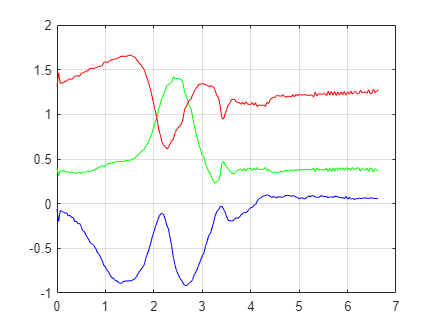

%Plot theta vs time
plot(tspan,theta0,'g')
hold on
plot(tspan,theta1,'r')
plot(tspan,theta2,'b')
hold off
grid on

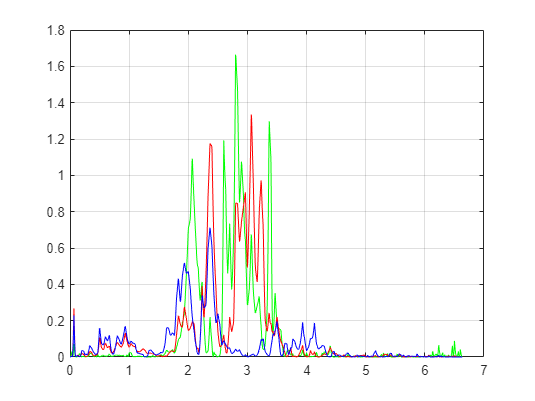


%Plot omega vs time
plot(tspan,omega0,'g')
hold on
plot(tspan,omega1,'r')
plot(tspan,omega2,'b')
hold off
grid on

%% Simmechanic
x0inp = [tspan x0ref];
y0inp = [tspan y0ref];

theta0inp = [tspan theta0];
theta1inp = [tspan theta1];
theta2inp = [tspan theta2];

% omega0inp = [tspan omega0];
% omega1inp = [tspan omega1];
% omega2inp = [tspan omega2];
s = sim('SimModel.slx');